## **Výpočet dynamiky klikového mechanismu**

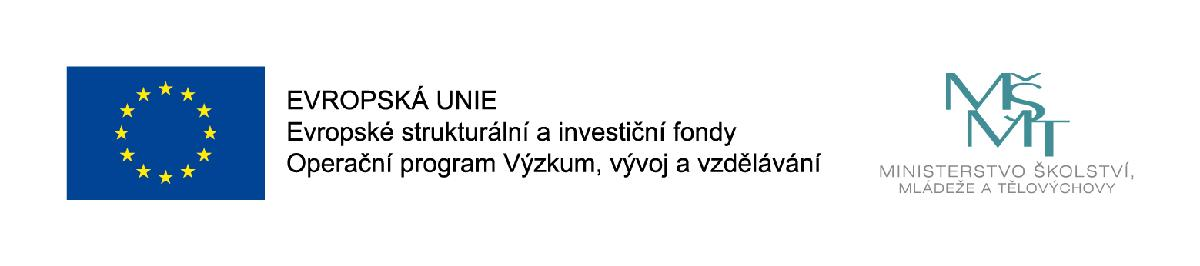

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

%Dialog Box 
%prompt = {'Connecting Rod Length [m]:','Crankpin Radius (half-stroke)[m]:','Bore [m]:','Piston Mass [kg]:','Connecting Rod Mass [kg]:','Combustion Chamber Height [m]','Maximum Pressure [Pa]:','Angular Velocity [RPM]:'}; 
%title = 'Introduce Engine Characteristics'; 
%dims = [1 60]; 
%definput = {'0.08','0.025','0.065','0.322','0.155','0.008','80e5','4000'}; answer = inputdlg(prompt,title,dims,definput); 
%VectorDatos=str2double(answer);
%clear title 
%constantes 
%l=VectorDatos(1,1);                 % Délka ojnice [m]:
%r=VectorDatos(2,1);                 % Poloměr klikového hřídele [m]
%B=VectorDatos(3,1);                 % Vrtání [m]
%Mp=VectorDatos(4,1);                % Hmotnost pístu [kg]
%Mcon=VectorDatos(5,1);              % Hmotnost ojnice [kg] 
%Hcc=VectorDatos(6,1);               % Výška spalovacího prostoru [m]
%Pmax=VectorDatos(7,1);              % Maximální tlak [Pa]
%w=VectorDatos(8,1)*((2*pi)/60);     % Úhlová rychlost [Hz]

clear;
l=0.08;                             % [m] Délka ojnice 
r=0.025;                            % [m] Poloměr klikového hřídele 
B=0.065;                            % [m] Vrtání 
Mp = 0.322;                         % [kg] Hmotnost pístu 
Mcon= 0.155;                        % [kg] Hmotnost ojnice 
Hcc=0.008;                          % [m] Výška spalovacího prostoru 
Pmax=80e5;                          % [Pa] Maximální tlak 
w = 4000*((2*pi)/60);               % [Hz] Úhlová rychlost 



A=0; 
Patm=100000; 
gam=1.4; 
% Oscilační hmota
MR=Mp+(0.5*Mcon); 
% Objem spalovací komory / válce 
Vcc=Hcc*((pi*B^2)/4); 
% Okamžitý tlak 0 < phi <180
Pins1=Patm; 
% Okamžitý tlak A = 360
Pins3=Pmax; 
% Okamžitý tlak A = 540
Pins5=Patm; 
while 0<=A && A<=180 
  % aby byly funkce diferencovatelné
    Eq1=((r^2)*((cosd(A)^2)-(sind(A)^2)))/sqrt((l^2)-(r^2*(sind(A)^2))); 
    Eq2=((r^4)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*(sind(A)^2))))^(3); 
    % Poloha pístu
    x=r*cosd(A)+sqrt((l^2)-(r^2)*(sind(A))^2); 
    % Rychlost pístu
    v=(-(r*sind(A))-((r^2)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*((sind(A))^2)))))*w;     %Aceleración 
    a=((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...
    (r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A))*w^2;
    % Počáteční síly
    F1=MR*(r*cosd(A)-Eq1-Eq2)*w^2; 
    % Kroutící moment 
    Tl=(MR*r*sind(A)*(1+(r/l)*cosd(A))*((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...
    (r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A)))*w^2;
    % Sila od plynu ve válci
    Fg=(Pmax*pi*B^2)/4;
    
    % Okamžitý objem 
    Vins=(((l+r)-x)*(pi*B^2)/4)+Vcc; 
    P=Pins1; 
    % Tlak plynu 
    Pg=P-Patm; 
    Tg=Pg*((pi*B^2)/4)*r*sind(A)*(1+(r/l)*cosd(A));     
    A=A+1; 
    VPg(A,1)=Pg; 
    VX(A,1)=x; 
    VA(A,1)=A; 
    VV(A,1)=v; 
    VAC(A,1)=a; 
    VTl(A,1)=Tl; 
    VTg(A,1)=Tg;   
 end 
 while 180<A && A<360
    % aby byly funkce diferencovatelné 
    Eq1=((r^2)*((cosd(A)^2)-(sind(A)^2)))/sqrt((l^2)-(r^2*(sind(A)^2))); 
    Eq2=((r^4)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*(sind(A)^2))))^(3); 
    % Poloha pístu 
    x=r*cosd(A)+sqrt((l^2)-(r^2)*(sind(A))^2); 
    % Rychlost pístu 
    v=(-(r*sind(A))-((r^2)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*((sind(A))^2)))))*w;     %Aceleración 
    a=((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...   
    (r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A))*w^2;
    
    % Počáteční síly 
    F1=MR*(r*cosd(A)-Eq1-Eq2)*w^2; 
    % Krouticí moment 
    Tl=(MR*r*sind(A)*(1+(r/l)*cosd(A))*((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...    
    (r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A)))*w^2; 
    % Plynná síla 
    Fg=(Pmax*pi*B^2)/4; 
    % Okamžitý objem 
    Vins=(((l+r)-x)*(pi*B^2)/4)+Vcc; 
    % Okamžitý tlak 180 <A <360
    Pins2=Patm+((Patm*((2*r*(pi*B^2)/4)+Vcc)^gam)*(Vins)^(-gam));     P=Pins2; 
    % Tlak plynu 
    Pg=P-Patm; 
    Tg=Pg*((pi*B^2)/4)*r*sind(A)*(1+(r/l)*cosd(A)); 
    A=A+1; 
    VPg(A,1)=Pg; 
    VX(A,1)=x; 
    VA(A,1)=A; 
    VV(A,1)=v; 
    VAC(A,1)=a; 
    VTl(A,1)=Tl; 
    VTg(A,1)=Tg;
end
if A==360   
    % aby byly funkce diferencovatelné
    Eq1=((r^2)*((cosd(A)^2)-(sind(A)^2)))/sqrt((l^2)-(r^2*(sind(A)^2)));     
    Eq2=((r^4)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*(sind(A)^2))))^(3);     % Posición del pistón 
    x=r*cosd(A)+sqrt((l^2)-(r^2)*(sind(A))^2); 
    
    % Rychlost pístu 
    v=(-(r*sind(A))-((r^2)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*((sind(A))^2)))))*w;     %Aceleración 
    a=((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...
    (r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A))*w^2;
    
    % Počáteční síly 
    F1=MR*(r*cosd(A)-Eq1-Eq2)*w^2; 
    % Kroutící moment 
    Tl=(MR*r*sind(A)*(1+(r/l)*cosd(A))*((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...    
    (r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A)))*w^2; 
    
    % Plynná síla
    Fg=(Pmax*pi*B^2)/4; 
    % Okamžitý objem
    Vins=(((l+r)-x)*(pi*B^2)/4)+Vcc; 
    P=Pins3; 
    % Tlak plynu 
    Pg=P-Patm; 
    Tg=Pg*((pi*B^2)/4)*r*sind(A)*(1+(r/l)*cosd(A));     
    A=A+1; 
    VPg(A,1)=Pg; 
    VX(A,1)=x; 
    VA(A,1)=A; 
    VV(A,1)=v; 
    VAC(A,1)=a; 
    VTl(A,1)=Tl; 
    VTg(A,1)=Tg; 
end;

while 360<A && A<540   
    % aby byly funkce diferencovatelné 
    Eq1=((r^2)*((cosd(A)^2)-(sind(A)^2)))/sqrt((l^2)-(r^2*(sind(A)^2))); 
    Eq2=((r^4)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*(sind(A)^2))))^(3); 
    % Poloha pístu 
    x=r*cosd(A)+sqrt((l^2)-(r^2)*(sind(A))^2) ;
    % Rychlost pístu 
    v=(-(r*sind(A))-((r^2)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*((sind(A))^2)))))*w;     %Aceleración 
    a=((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...
    (r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A))*w^2;
    
    % Počáteční síly
    F1=MR*(r*cosd(A)-Eq1-Eq2)*w^2; 
    % Kroutící moemnt 
    Tl=(MR*r*sind(A)*(1+(r/l)*cosd(A))*((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...    
    (r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A)))*w^2;
    
    % Plynná síla 
    Fg=(Pmax*pi*B^2)/4; 
    % Okamžitý objem
    Vins=(((l+r)-x)*(pi*B^2)/4)+Vcc; 
    Pins4=Patm+((Pmax*(Vcc)^gam)*(Vins)^(-gam));     
    P=Pins4; 
    % Tlak plynu
    Pg=P-Patm; 
    Tg=Pg*((pi*B^2)/4)*r*sind(A)*(1+(r/l)*cosd(A));     
    A=A+1; 
    VPg(A,1)=Pg; 
    
    VX(A,1)=x;     
    VA(A,1)=A;     
    VV(A,1)=v;
    VAC(A,1)=a;
    Tl(A,1)=Tl;

    VTg(A,1)=Tg;
    
end;
while 540<=A && A<=720
    %haciendo las funciones derivables 
    Eq1=((r^2)*((cosd(A)^2)-(sind(A)^2)))/sqrt((l^2)-(r^2*(sind(A)^2))); 
    Eq2=((r^4)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*(sind(A)^2))))^(3); 
    % Poloha pístu
    x=r*cosd(A)+sqrt((l^2)-(r^2)*(sind(A))^2); 
    % Rychlost pístu
    v=(-(r*sind(A))-((r^2)*((cosd(A)*sind(A))))/(sqrt((l^2)-(r^2*((sind(A))^2)))))*w;     % zrychlení
    a=((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...   
    (r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A))*w^2;
    
    % Počáteční síly 
    F1=MR*(r*cosd(A)-Eq1-Eq2)*w^2; 
    % Kroutící moment 
    Tl=(MR*r*sind(A)*(1+(r/l)*cosd(A))*((r^2*sind(A)^2)/sqrt(l^2-r^2*sind(A)^2)-...
    (r^2*cosd(A)^2)/sqrt(l^2-r^2*sind(A)^2)-(r^4*cosd(A)^2*sind(A)^2)/(l^2-r^2*sind(A)^2)^(3/2)-r*cosd(A)))*w^2; 
    
    % Plynná síla
    Fg=(Pmax*pi*B^2)/4; 
    % Okamžitý objem 
    Vins=(((l+r)-x)*(pi*B^2)/4)+Vcc; 
    P=Pins5; 
    % Tlak plynu
    Pg=P-Patm; 
    Tg=Pg*((pi*B^2)/4)*r*sind(A)*(1+(r/l)*cosd(A));     
    A=A+1; 
    VPg(A,1)=Pg; 
    VX(A,1)=x; 
    VA(A,1)=A; 
    VV(A,1)=v; 
    VAC(A,1)=a; 
    VTl(A,1)=Tl; 
    VTg(A,1)=Tg; 
    
    end 
VTg2=VTg; 
VSuma=(VTl+VTg2); 

### Kreslení grafů

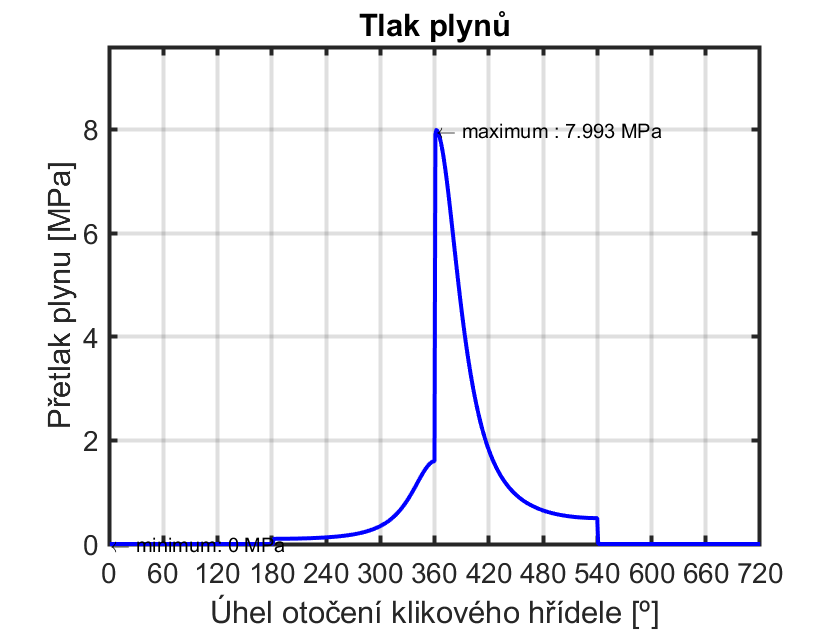

figure
plot(VA,Pa2MPa(VPg),'-b','linewidth',2);
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
ax1.XTick = 0:60:720;
axis([ax1],[0 720 0 max(Pa2MPa(VPg))*1.2]) 
title('Tlak plynů') 
xlabel('Úhel otočení klikového hřídele [º]') 
ylabel('Přetlak plynu [MPa]') 
grid on;
[ValPg, idxPg] = max(VPg); 
txt = ['\leftarrow maximum : ' num2str(Pa2MPa(ValPg)) ' MPa']; 
text(idxPg,Pa2MPa(ValPg),txt) 
[ValPg2, idxPg2] = min(VPg); 
txt2 = ['\leftarrow minimum: ' num2str(Pa2MPa(ValPg2)) ' MPa']; 
text(idxPg2,ValPg2,txt2); 

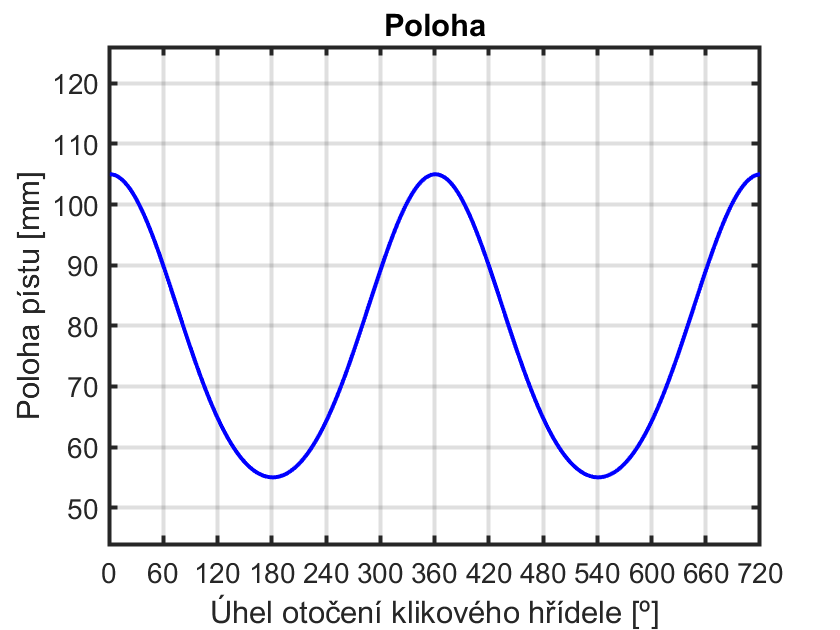

figure
plot(VA,m2mm(VX),'-b','linewidth',2) 
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
ax1.XTick = 0:60:720;
axis([ax1],[0 720 min(m2mm(VX))*0.8 max(m2mm(VX))*1.2]) 
title('Poloha') 
xlabel('Úhel otočení klikového hřídele [º]') 
ylabel('Poloha pístu [mm]') 
grid on;

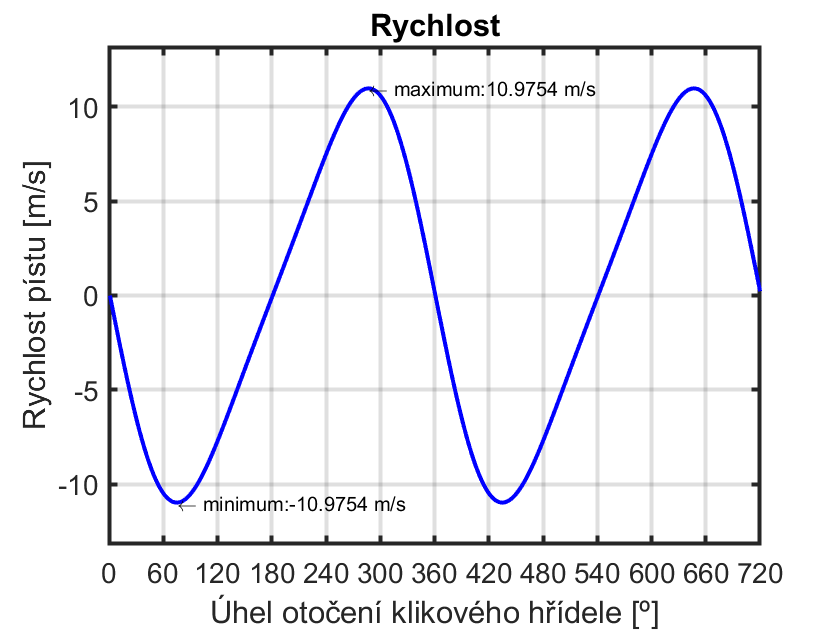

figure
plot(VA,VV,'-b','linewidth',2) 
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
ax1.XTick = 0:60:720;
axis([ax1],[0 720 min(VV)*1.2 max(VV)*1.2]) 
grid on
title('Rychlost') 
xlabel('Úhel otočení klikového hřídele [º]') 
ylabel('Rychlost pístu [m/s]') 
[ValV, idxV] = max(VV); 
txt = ['\leftarrow maximum:' num2str(ValV) ' m/s']; 
text(idxV,ValV,txt) 
[ValV2, idxV2] = min(VV); 
txt2 = ['\leftarrow minimum:' num2str(ValV2) ' m/s']; 
text(idxV2,ValV2,txt2); 

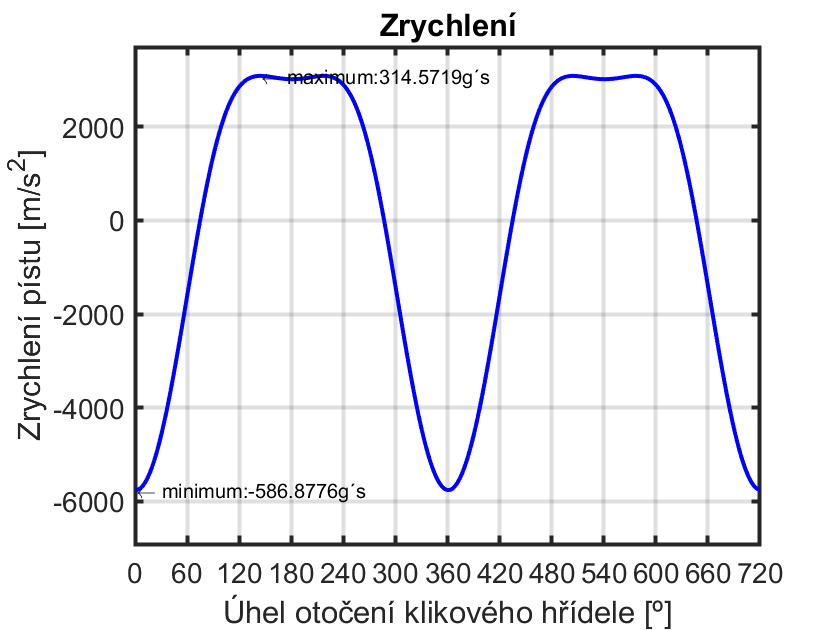

figure
plot(VA,VAC,'-b','linewidth',2) 
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
ax1.XTick = 0:60:720;
axis([ax1],[0 720 min(VAC)*1.2 max(VAC)*1.2]) 
grid on
title('Zrychlení') 
xlabel('Úhel otočení klikového hřídele [º]') 
ylabel('Zrychlení pístu [m/s^2]') 
[ValAC, idxAC] = max(VAC); 
[ValAC2, idxAC2] = min(VAC); 
txt = ['\leftarrow maximum:' num2str(ValAC/9.81) 'g´s']; 
text(idxAC,ValAC,txt) 
txt2 = ['\leftarrow minimum:' num2str(ValAC2/9.81) 'g´s']; 
text(idxAC2,ValAC2,txt2); 

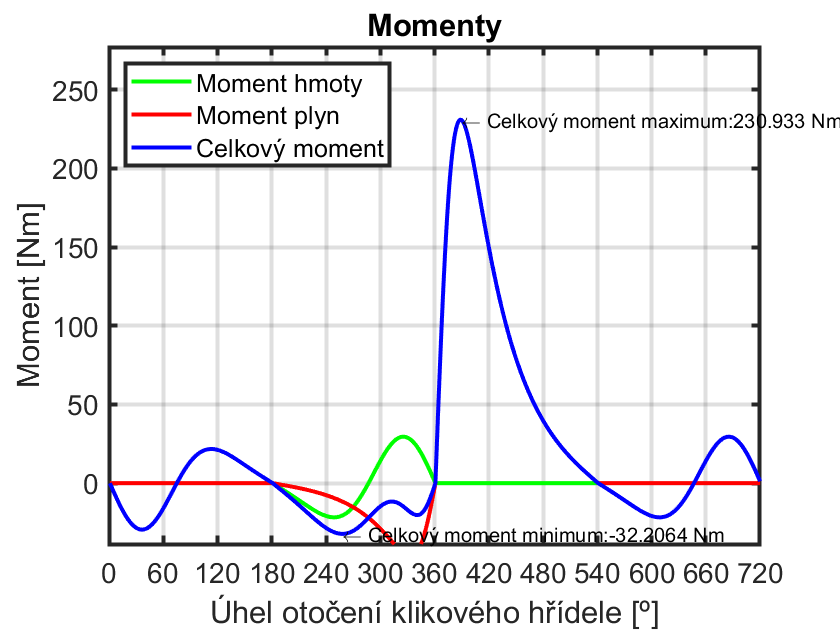

figure
plot(VA,VTl,'-g','linewidth',2) 
hold on 
[ValVTl, idxVTl] = max(VTl); 
[ValVTl2, idxVTl2] = min(VTl); 
plot(VA,VTg2,'-r','linewidth',2) 
[ValVTg2, idxVTg2] = max(VTg2); 
[ValVTg22, idxVTg22] = min(VTg2); 
plot(VA,VSuma,'-b','linewidth',2) 
[ValVSuma, idxVSuma] = max(VSuma); 
[ValVSuma2, idxVSuma2] = min(VSuma); 
hold off 
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
ax1.XTick = 0:60:720;
axis([ax1],[0 720 min(VSuma)*1.2 max(VSuma)*1.2]) 
grid on

txt = ['\leftarrow Celkový moment maximum:' num2str(ValVSuma) ' Nm']; 
text(idxVSuma,ValVSuma,txt) 
txt2 = ['\leftarrow Celkový moment minimum:' num2str(ValVSuma2) ' Nm']; 
text(idxVSuma2,ValVSuma2,txt2); 
xlabel('Úhel otočení klikového hřídele [º]') 
ylabel('Moment [Nm]') 
title('Momenty') 
legend({'Moment hmoty','Moment plyn','Celkový moment'},'Location','northwest') 

### Lokální funkce 

Univerzální plynová konstanta

function [result] = Rm
   result = 8314.3;              
end   

Převádí teplotu ve stupních Celsia na Kelvíny

function [K] = C2K(C)
K = C+273.15;
end

Převádí hektopascaly na Pascaly

function [Pa] = hPa2Pa(hPa)
Pa = hPa*100;
end 

Převod litrů

function [m3] = l2m3(l)
m3 = l*.001;
end

Převod Pascalů

function [kPa] = Pa2kPa(Pa)
kPa = Pa/1000;
end

Převod Watů

function [kW] = W2kW(W)
kW = W/1000;
end

Převod

function [mm] = m2mm(m)
mm = m*1000;
end

Převod

function [MPa] = Pa2MPa(Pa)
MPa = Pa*0.000001;
end